# Підготовка

clear; close all; clc;

## 1-2. Завантаження і відображення тестового зображення

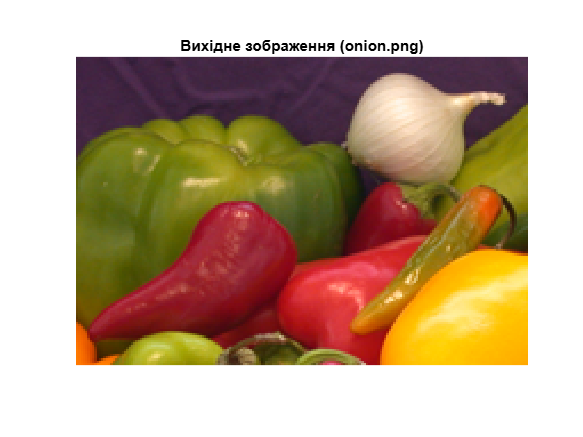

I = im2double(imread('onion.png'));

figure;
imshow(I);
title('Вихідне зображення (onion.png)');

## 3-4. Перекручення зображення, змінюючи параметри LEN і THETA

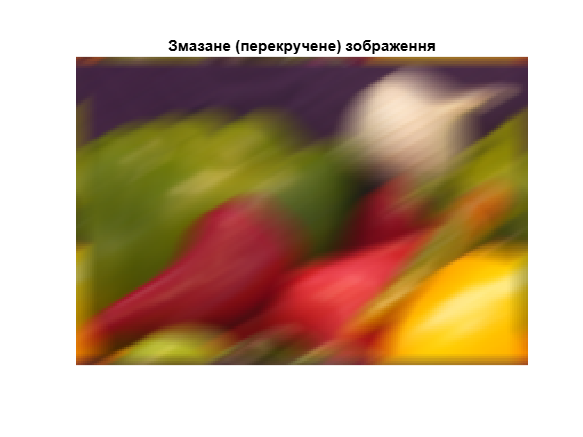

LEN = 21;     % Довжина розмиття
THETA = 30;   % Кут розмиття
PSF = fspecial('motion', LEN, THETA);  % PSF (Point Spread Function) - ядро згортки, що відповідає розмиттю під час руху

% Згортка зображення з PSF:
blurred = imfilter(I, PSF, 'conv', 'circular');
% 'conv' означає згортку, 'circular' — граничні умови (зображення повторюється циклічно)

figure;
imshow(blurred);
title('Змазане (перекручене) зображення');

## 5-6. Відновлення зображення

Використовуємо метод Вінера (Wiener) через функцію deconvwnr. Якщо шум не враховується (ідеальне відновлення без шуму), можна вказати NSR=0.

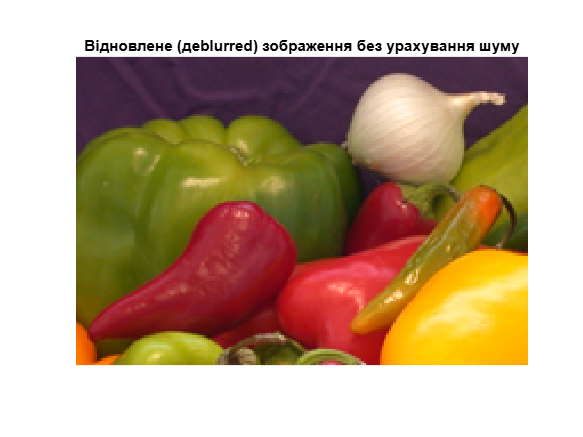

wnr1 = deconvwnr(blurred, PSF, 0);  
% Тут 0 означає, що шуму немає або він дуже малий (NSR=0).

figure;
imshow(wnr1);
title('Відновлене (деblurred) зображення без урахування шуму');

## 7. Зашумлення початкового зображення та повторення пунктів 2-6

7.1. Додаємо шум до вихідного зображення (гаусівський шум)

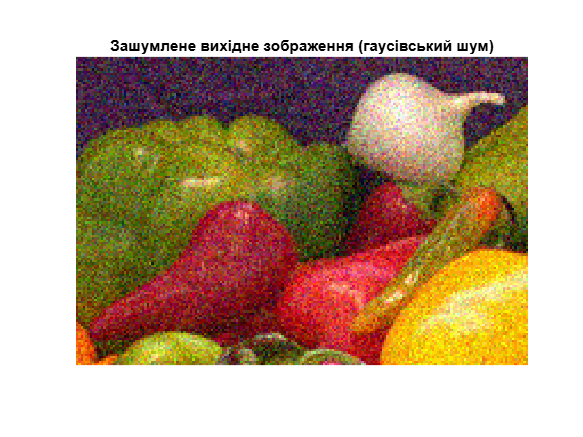

noisy = imnoise(I, 'gaussian', 0, 0.01);  

figure;
imshow(noisy);
title('Зашумлене вихідне зображення (гаусівський шум)');

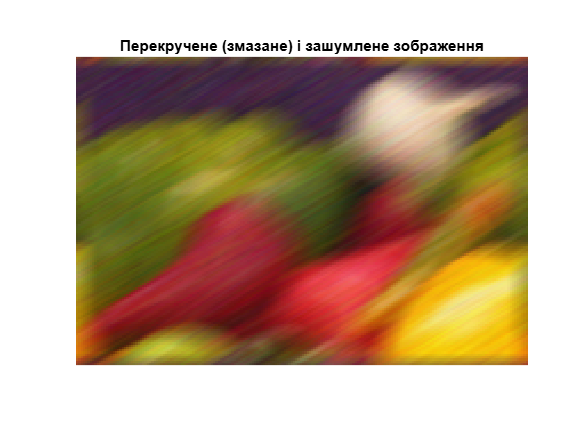


noisy_blurred = imfilter(noisy, PSF, 'conv', 'circular');

figure;
imshow(noisy_blurred);
title('Перекручене (змазане) і зашумлене зображення');

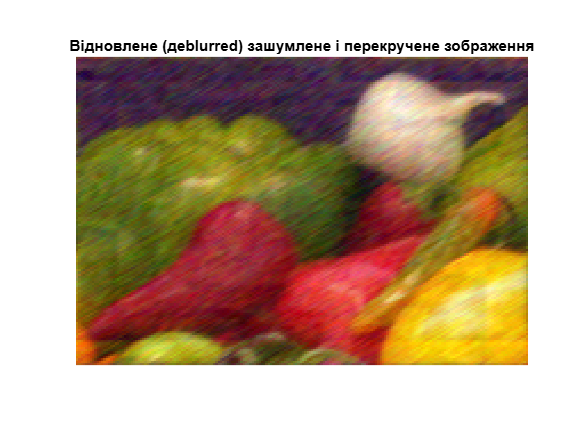


wnr2 = deconvwnr(noisy_blurred, PSF, 0.01);

figure;
imshow(wnr2);
title('Відновлене (деblurred) зашумлене і перекручене зображення');

## 8. Відповіді на питання:

**1.** **Поясніть процес формування зображення. **

Формування зображення починається з того, що світло, яке падає на об’єкт, проходить через оптичну систему камери (лінзи) та фокусується на сенсорі. Сенсор перетворює отримане світло на електричні сигнали, які потім оцифровуються у вигляді масиву пікселів. Таким чином, цифрове зображення являє собою дискретне представлення просторового розподілу яскравості та кольорів.

**2. Опишіть модель формування зображень та лінійних перекручень.**

Модель формування зображення базується на уявленні, що спостережуване зображення отримується шляхом згортки оригінального зображення з функцією розсіювання яка описує спотворюючий вплив системи, плюс додавання адитивного шуму. У лабораторній роботі для моделювання рухової розмитості ми використовуємо фільтр типу "motion" (за допомогою fspecial), де параметри LEN і THETA визначають довжину та кут руху. Ця модель вважає, що перекручення є лінійними та інваріантними щодо зсувів, тобто однаковими для всіх точок зображення.

**3. Поясніть процес відновлення перекрученого зображення.**

Відновлення зображення – це процес, який намагається відмінити ефект розмиття, описаний згорткою з функцією розсіювання. Основна ідея полягає в тому, щоб за допомогою зворотної згортки отримати оцінку оригінального зображення, мінімізуючи вплив шуму. У нашій лабораторній роботі використовується метод Вінера (функція deconvwnr), який враховує співвідношення сигнал/шум та допомагає відновити деталі, зменшуючи розмиття. Проте, через наявність шуму та неточності в моделі PSF, відновлення рідко є ідеальним – отримане зображення може містити артефакти, але загалом метод дозволяє значно покращити різкість порівняно з перекрученим зображенням.